%% Project saved tip displacement onto initial tip-section E2/E3 axes

% matFile = fullfile(pwd, 'Jeong-results(new7).mat');
matFile = fullfile(pwd, 'Aditya-Case-II-results(new11).mat');

S = load(matFile, 'caseInfo', 'result');
caseInfo = S.caseInfo;
result = S.result;

t = result.t(:).';

if isfield(caseInfo, 'nodenum')
    tipNode = caseInfo.nodenum;
else
    tipNode = size(result.q, 1) / 7;
end

tipDof = (tipNode - 1) * 7 + (1:7);

rTip0 = result.q(tipDof(1:3), 1);
qTip0 = result.q(tipDof(4:7), 1);

rTip = result.q(tipDof(1:3), :);
uTip = rTip - rTip0;

R0_tip = quatToRot(qTip0);

uTipLocal0 = R0_tip.' * uTip;

tipSpanwise_E1 = uTipLocal0(1, :);
tipEdgewise_E2 = uTipLocal0(2, :);
tipFlapwise_E3 = uTipLocal0(3, :);

fprintf('Final tip E2 edgewise displacement = %.6f m\n', tipEdgewise_E2(end));

Final tip E2 edgewise displacement = 0.604677 m


fprintf('Final tip E3 flapwise displacement = %.6f m\n', tipFlapwise_E3(end));

Final tip E3 flapwise displacement = -4.901751 m



if isfield(caseInfo, 'OmegaHub')
    lastRev = t >= max(0, t(end) - 2*pi/caseInfo.OmegaHub);
    fprintf('Last-rev mean E2 edgewise displacement = %.6f m\n', ...
        mean(tipEdgewise_E2(lastRev)));
    fprintf('Last-rev mean E3 flapwise displacement = %.6f m\n', ...
        mean(tipFlapwise_E3(lastRev)));
end

Last-rev mean E2 edgewise displacement = 0.610905 m


Last-rev mean E3 flapwise displacement = -4.902324 m


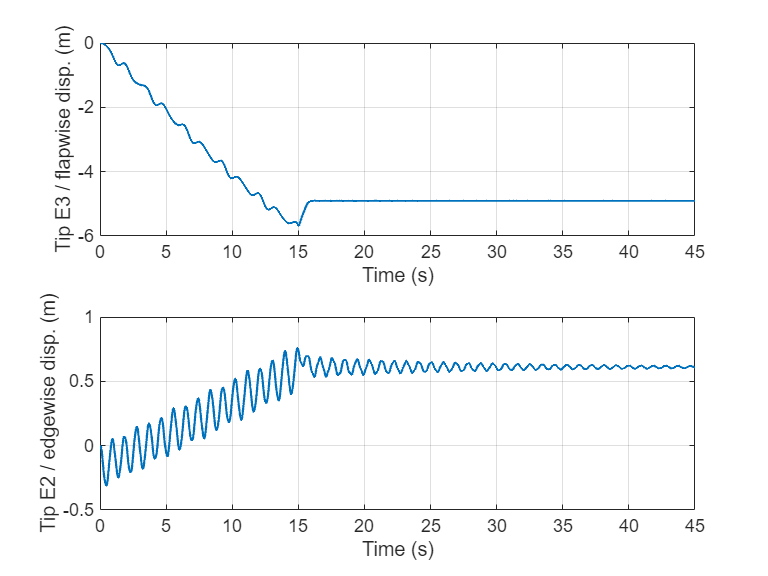


figure('Name', 'Tip displacement in initial tip-section frame');
tiledlayout(2, 1)

nexttile
plot(t, tipFlapwise_E3, 'LineWidth', 1.1)
xlabel('Time (s)')
ylabel('Tip E3 / flapwise disp. (m)')
grid on

nexttile
plot(t, tipEdgewise_E2, 'LineWidth', 1.1)
xlabel('Time (s)')
ylabel('Tip E2 / edgewise disp. (m)')
grid on


function R = quatToRot(q)
    q = q(:) / norm(q);
    e0 = q(1);
    e1 = q(2);
    e2 = q(3);
    e3 = q(4);

    E1 = [e0^2 + e1^2 - e2^2 - e3^2;
          2 * (e1*e2 + e0*e3);
          2 * (e1*e3 - e0*e2)];

    E2 = [2 * (e1*e2 - e0*e3);
          e0^2 - e1^2 + e2^2 - e3^2;
          2 * (e2*e3 + e0*e1)];

    E3 = [2 * (e1*e3 + e0*e2);
          2 * (e2*e3 - e0*e1);
          e0^2 - e1^2 - e2^2 + e3^2];

    R = [E1, E2, E3];
end


## 4 figures: tangential force/normal force/deflection/elastic theta

%% postprocessWindTurbineBladeResults_Gauss.m
% Read result file saved by saveResults.m and plot Gauss-point distributions:
% 1) axial load distribution
% 2) tangential load distribution
% 3) flapwise/edgewise deflection distribution
% 4) elastic twist distribution

clear; clc;

%% User settings
matFile = '';       % Empty: select file interactively
plotIndex = [];     % Empty: use the last valid time step
plotTime = [];      % If non-empty, use nearest time instead of plotIndex

saveFigures = true;
outputDir = '';     % Empty: use the same folder as matFile

applyLoadScaleToAero = true;

edgewiseSign =  1;   % E2_ref direction
flapwiseSign = -1;   % E3_ref direction

%% Load data
if isempty(matFile)
    [fileName, filePath] = uigetfile('*.mat', 'Select saved result mat file');
    if isequal(fileName, 0)
        error('No mat file selected.');
    end
    matFile = fullfile(filePath, fileName);
end

data = load(matFile, 'caseInfo', 'result');
caseInfo = data.caseInfo;
result = data.result;

if isempty(outputDir)
    outputDir = fileparts(matFile);
end

t = result.t(:);
nStep = numel(t);

%% Select time step
if ~isempty(plotTime)
    [~, stepID] = min(abs(t - plotTime));
elseif ~isempty(plotIndex)
    stepID = plotIndex;
else
    if isfield(result, 'aero') && isfield(result.aero, 'validStep') ...
            && ~isempty(result.aero.validStep)
        stepID = result.aero.validStep(end);
    else
        stepID = nStep;
    end
end

fprintf('Post-processing file:\n  %s\n', matFile);

Post-processing file:
  E:\Program-WangFeng\Github repository\GEB_quaternion\GEF_OOP_matlab\examples\windTurbineBLade\Jeong-results(new7).mat


fprintf('Selected step = %d, t = %.6f s\n', stepID, t(stepID));

Selected step = 4501, t = 45.000000 s


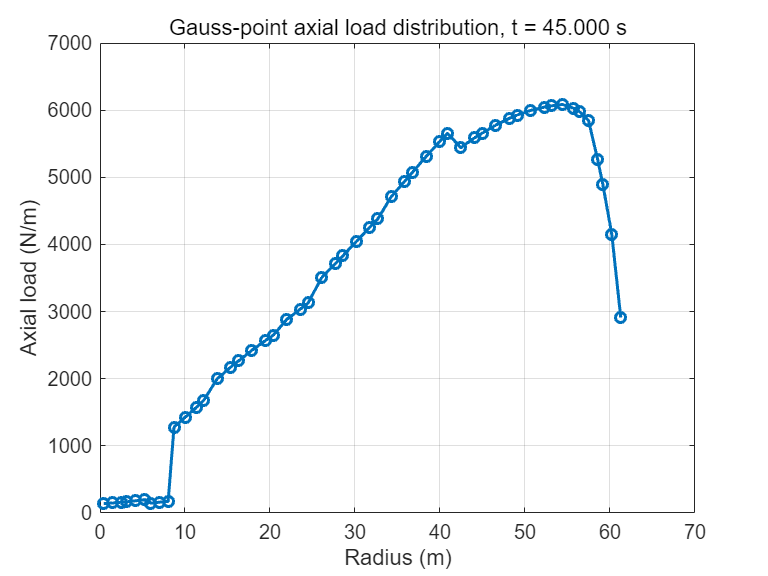

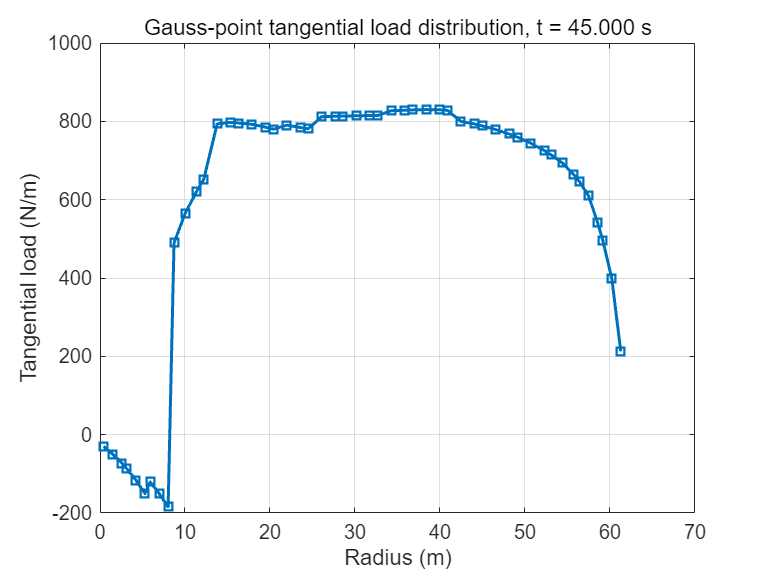

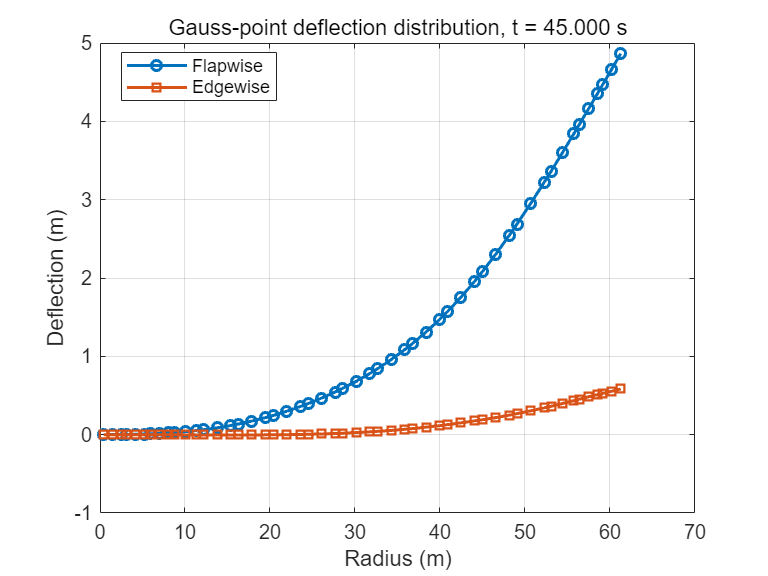

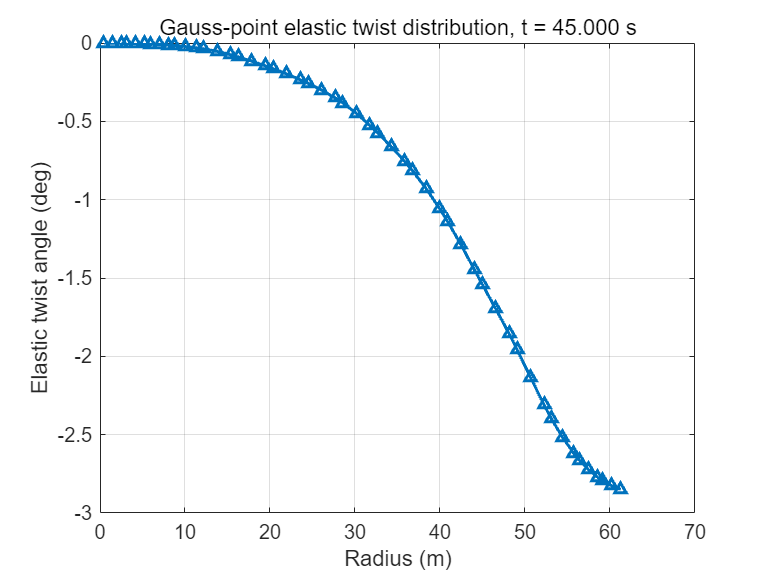

Figures saved to:
  E:\Program-WangFeng\Github repository\GEB_quaternion\GEF_OOP_matlab\examples\windTurbineBLade



%% Extract Gauss-point aerodynamic data
aeroGauss = result.aero.gauss;

radiusGauss = aeroGauss.radius(:, stepID);
axialLoad = aeroGauss.normalForce(:, stepID);
tangentialLoad = aeroGauss.tangentialForce(:, stepID);

if applyLoadScaleToAero && isfield(result.aero, 'loadScale')
    loadScale = result.aero.loadScale(stepID);
    axialLoad = loadScale * axialLoad;
    tangentialLoad = loadScale * tangentialLoad;
end

if isfield(aeroGauss, 'thetaElasticDeg')
    thetaElasticDeg = aeroGauss.thetaElasticDeg(:, stepID);
else
    thetaElasticDeg = rad2deg(aeroGauss.thetaElastic(:, stepID));
end

elementID = aeroGauss.elementID(:, stepID);
xiGauss = aeroGauss.xi(:, stepID);

valid = isfinite(radiusGauss) ...
    & isfinite(axialLoad) ...
    & isfinite(tangentialLoad) ...
    & isfinite(thetaElasticDeg) ...
    & isfinite(elementID) ...
    & isfinite(xiGauss);

radiusGauss = radiusGauss(valid);
axialLoad = axialLoad(valid);
tangentialLoad = tangentialLoad(valid);
thetaElasticDeg = thetaElasticDeg(valid);
elementID = elementID(valid);
xiGauss = xiGauss(valid);

%% Compute flapwise/edgewise deflection at Gauss points
q = result.q;
radiusNode = caseInfo.radius(:);

nNode = size(q, 1) / 7;
if abs(nNode - round(nNode)) > 0
    error('The size of result.q is not compatible with 7 DOFs per node.');
end
nNode = round(nNode);

flapwiseDef = nan(size(radiusGauss));
edgewiseDef = nan(size(radiusGauss));

for k = 1:numel(radiusGauss)
    e = round(elementID(k));
    xi = xiGauss(k);

    nodeID = [2*e - 1, 2*e, 2*e + 1];
    if any(nodeID < 1) || any(nodeID > nNode)
        continue
    end

    N1 = 0.5 * xi * (xi - 1);
    N2 = 1 - xi^2;
    N3 = 0.5 * xi * (xi + 1);
    N = [N1, N2, N3];

    r0 = zeros(3, 1);
    rt = zeros(3, 1);
    qRef = zeros(4, 1);

    for a = 1:3
        id = (nodeID(a) - 1) * 7 + (1:7);

        r0 = r0 + N(a) * q(id(1:3), 1);
        rt = rt + N(a) * q(id(1:3), stepID);
        qRef = qRef + N(a) * q(id(4:7), 1);
    end

    qRef = qRef / norm(qRef);
    ARef = quatToRotMatScalarFirst(qRef);

    dr = rt - r0;
    E2Ref = ARef(:, 2);
    E3Ref = ARef(:, 3);

    edgewiseDef(k) = edgewiseSign * dot(dr, E2Ref);
    flapwiseDef(k) = flapwiseSign * dot(dr, E3Ref);
end

%% Sort by radius
[radiusGauss, sortID] = sort(radiusGauss);

axialLoad = axialLoad(sortID);
tangentialLoad = tangentialLoad(sortID);
thetaElasticDeg = thetaElasticDeg(sortID);
flapwiseDef = flapwiseDef(sortID);
edgewiseDef = edgewiseDef(sortID);

%% Figure 1: axial load distribution
fig1 = figure('Name', 'Gauss-point axial load distribution', 'Color', 'w');
plot(radiusGauss-1.5, axialLoad, 'o-', 'LineWidth', 1.5, 'MarkerSize', 5);
grid on; box on;
xlabel('Radius (m)');
ylabel('Axial load (N/m)');
title(sprintf('Gauss-point axial load distribution, t = %.3f s', t(stepID)));

%% Figure 2: tangential load distribution
fig2 = figure('Name', 'Gauss-point tangential load distribution', 'Color', 'w');
plot(radiusGauss-1.5, tangentialLoad, 's-', 'LineWidth', 1.5, 'MarkerSize', 5);
grid on; box on;
xlabel('Radius (m)');
ylabel('Tangential load (N/m)');
title(sprintf('Gauss-point tangential load distribution, t = %.3f s', t(stepID)));

%% Figure 3: flapwise and edgewise deflection distribution
fig3 = figure('Name', 'Gauss-point blade deflection distribution', 'Color', 'w');
plot(radiusGauss-1.5, flapwiseDef, 'o-', 'LineWidth', 1.5, 'MarkerSize', 5); hold on;
plot(radiusGauss-1.5, edgewiseDef, 's-', 'LineWidth', 1.5, 'MarkerSize', 5);
grid on; box on;
xlabel('Radius (m)');
ylabel('Deflection (m)');
legend('Flapwise', 'Edgewise', 'Location', 'best');
title(sprintf('Gauss-point deflection distribution, t = %.3f s', t(stepID)));

%% Figure 4: elastic twist distribution
fig4 = figure('Name', 'Gauss-point elastic twist distribution', 'Color', 'w');
plot(radiusGauss-1.5, -thetaElasticDeg, '^-', 'LineWidth', 1.5, 'MarkerSize', 5);
grid on; box on;
xlabel('Radius (m)');
ylabel('Elastic twist angle (deg)');
title(sprintf('Gauss-point elastic twist distribution, t = %.3f s', t(stepID)));

%% Save figures
if saveFigures
    tag = sprintf('gauss_step%06d_t%.3fs', stepID, t(stepID));
    tag = strrep(tag, '.', 'p');

    exportgraphics(fig1, fullfile(outputDir, ['axialLoad_' tag '.png']), 'Resolution', 300);
    exportgraphics(fig2, fullfile(outputDir, ['tangentialLoad_' tag '.png']), 'Resolution', 300);
    exportgraphics(fig3, fullfile(outputDir, ['deflection_' tag '.png']), 'Resolution', 300);
    exportgraphics(fig4, fullfile(outputDir, ['elasticTwist_' tag '.png']), 'Resolution', 300);

    fprintf('Figures saved to:\n  %s\n', outputDir);
end


%% Local function
function A = quatToRotMatScalarFirst(q)
    q = q(:) / norm(q);
    q0 = q(1);
    q1 = q(2);
    q2 = q(3);
    q3 = q(4);

    A = [ ...
        1 - 2*(q2^2 + q3^2), 2*(q1*q2 - q0*q3),     2*(q1*q3 + q0*q2);
        2*(q1*q2 + q0*q3),     1 - 2*(q1^2 + q3^2), 2*(q2*q3 - q0*q1);
        2*(q1*q3 - q0*q2),     2*(q2*q3 + q0*q1),     1 - 2*(q1^2 + q2^2)];
end